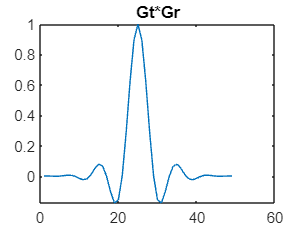

clear 
Tsymol=6;
n=100002; 
SNR = 0:2:30;
input=randsrc(1,n,[0 1]);


          
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ftiaxnv ta dio kanalia mazi me ta midenika toys
h1=[0.04 -0.05 0.07 -0.21 -0.5 0.72 0.36 0 0.21 0.03 0.07];
H1=zeros(size(h1).*[1,4]);
H1(1:4:end)=h1;

h2=[0.227 0.460 0.688 0.460 0.227];
H2=zeros(size(h2).*[1,4]);
H2(1:4:end)=h2;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%ftiaxnv filtro pompoy kai dekti
b = rcosdesign(0.3,6,4,'sqrt');
fvtool(b, 'Analysis' , 'impulse')

%ektiposeis ton ypersistimaton
 
 %idaniko kanali
 ypersysthma=conv(b,b);
 plot(ypersysthma)
 title('Gt*Gr' );

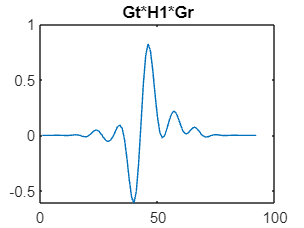


  
 %kanali h[-5 5]
 ypersysthma_1=conv(conv(b,H1),b);
 plot(ypersysthma_1)
 title('Gt*H1*Gr' );

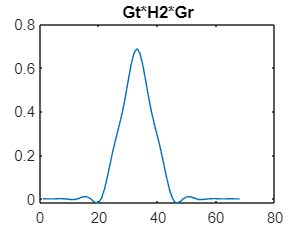

 
 
 %kanali h[-2 2]
 ypersysthma_2=conv(conv(b,H2),b);
 plot(ypersysthma_2)
 title('Gt*H2*Gr' );

 %hold off
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ARXH 4-PSK kai gia ta 3 kanalia
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
M=4;
p=mapper(input,M); 
p_teliko= zeros(length(p)*4,1);
p_teliko(1:4:end) = p;

phOffset = 0;      
symMap = 'Gray'; 
%ektiposi asterismoy
pskModulator = comm.PSKModulator(M,phOffset,'SymbolMapping',symMap)

pskModulator =   comm.PSKModulator with properties:

    ModulationOrder: 4
        PhaseOffset: 0
           BitInput: false
      SymbolMapping: 'Gray'
     OutputDataType: 'double'


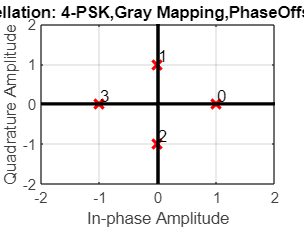

constellation(pskModulator)

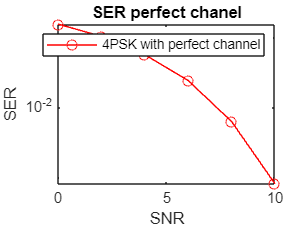




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GIA IDANIKO KANALI
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pompos_kanali=b;%mono to b afoy kanali idaniko

[SER1, BER1]=M_PSK(p_teliko,pompos_kanali,b,n,input,M);

%ektiposeis
semilogy(SNR,SER1,'ro-')
title('SER perfect chanel' )
xlabel('SNR');
ylabel('SER');
legend('4PSK with perfect channel');

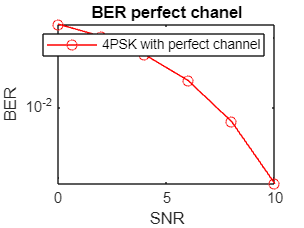


semilogy(SNR,BER1,'ro-')
title('BER perfect chanel' )
xlabel('SNR');
ylabel('BER');
legend('4PSK with perfect channel');

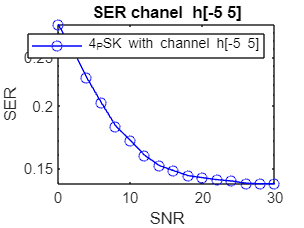

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GIA  KANALI H[-5 5]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pompos_kanali=conv(b,H1);

[SER2, BER2]=M_PSK(p_teliko,pompos_kanali,b,n,input,M);

%ektiposeis
semilogy(SNR,SER2,'bo-')
title('SER chanel  h[-5 5]' )
xlabel('SNR');
ylabel('SER');
legend('4_PSK with channel h[-5 5]');

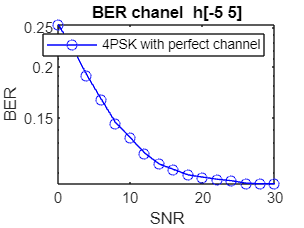


semilogy(SNR,BER2,'bo-')
title('BER chanel  h[-5 5]' )
xlabel('SNR');
ylabel('BER');
legend('4PSK with perfect channel');

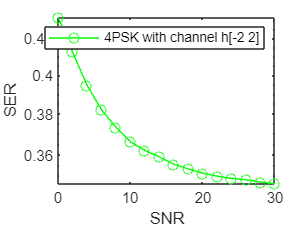

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GIA  KANALI H[-2 2]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pompos_kanali=conv(b,H2);

[SER3, BER3]=M_PSK(p_teliko,pompos_kanali,b,n,input,M);

%ektiposeis
semilogy(SNR,SER3,'go-')
xlabel('SNR');
ylabel('SER');
legend('4PSK with channel h[-2 2]')

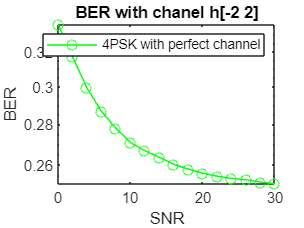


semilogy(SNR,BER3,'go-')
title('BER with chanel h[-2 2]')
xlabel('SNR');
ylabel('BER');
legend('4PSK with perfect channel');

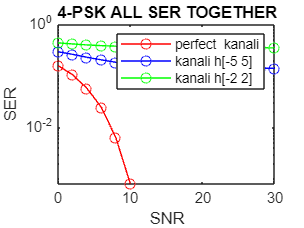

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ektiposi ola mazi SER
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
semilogy(SNR,SER1,'ro-')
hold on
semilogy(SNR,SER2,'bo-')
hold on
semilogy(SNR,SER3,'go-')
title('4-PSK ALL SER TOGETHER')
xlabel('SNR');
ylabel('SER');
legend('perfect  kanali','kanali h[-5 5]','kanali h[-2 2]')
hold off

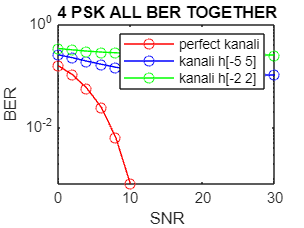


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ektiposi ola mazi BER
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
semilogy(SNR,BER1,'ro-')
hold on
semilogy(SNR,BER2,'bo-')
hold on
semilogy(SNR,BER3,'go-')
title('4 PSK ALL BER TOGETHER')
xlabel('SNR');
ylabel('BER');
legend('perfect kanali','kanali h[-5 5]','kanali h[-2 2]')
hold off

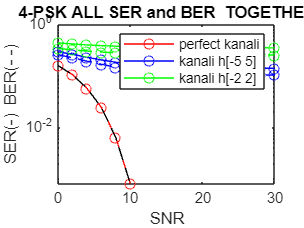




%BER KAI SER MAZI
semilogy(SNR,SER1,'ro-')
hold on
semilogy(SNR,SER2,'bo-')
hold on
semilogy(SNR,SER3,'go-')
hold on
semilogy(SNR,BER1,'black--')
hold on
semilogy(SNR,BER2,'bo--')
hold on
semilogy(SNR,BER3,'go--')
hold off
title('4-PSK ALL SER and BER  TOGETHER')
xlabel('SNR');
ylabel('SER(-)  BER(- -)');
legend('perfect kanali','kanali h[-5 5]','kanali h[-2 2]')
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TELOS 4-PSK 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ARXH  8-PSK
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear p;
M=8;
p=mapper(input,M); 
p_teliko= zeros(length(p)*4,1);
p_teliko(1:4:end) = p;


%ektiposi asterismoy
pskModulator = comm.PSKModulator(M,phOffset,'SymbolMapping',symMap)

pskModulator =   comm.PSKModulator with properties:

    ModulationOrder: 8
        PhaseOffset: 0
           BitInput: false
      SymbolMapping: 'Gray'
     OutputDataType: 'double'


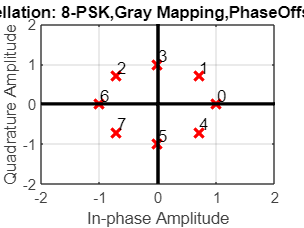

constellation(pskModulator)

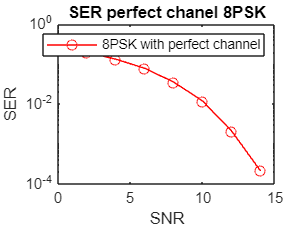



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GIA IDANIKO KANALI PSK
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pompos_kanali=b;%mono to b afoy kanali idaniko

[SER4, BER4]=M_PSK(p_teliko,pompos_kanali,b,n,input,M);

semilogy(SNR,SER4,'ro-')
title('SER perfect chanel 8PSK' )
xlabel('SNR');
ylabel('SER');
legend('8PSK with perfect channel');

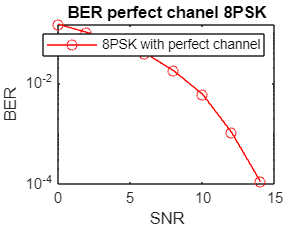


semilogy(SNR,BER4,'ro-')
title('BER perfect chanel 8PSK' )
xlabel('SNR');
ylabel('BER');
legend('8PSK with perfect channel');

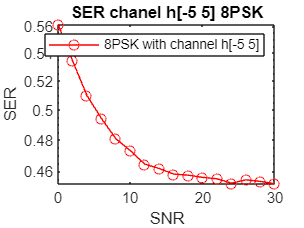

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%





%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GIA  KANALI h[-5 5]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pompos_kanali=conv(b,H1);
[SER5, BER5]=M_PSK(p_teliko,pompos_kanali,b,n,input,M);

semilogy(SNR,SER5,'ro-')
title('SER chanel h[-5 5] 8PSK' )
xlabel('SNR');
ylabel('SER');
legend('8PSK with channel h[-5 5]');

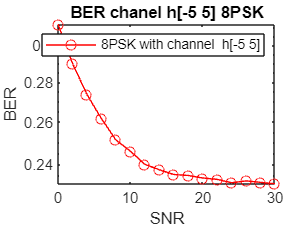


semilogy(SNR,BER5,'ro-')
title('BER chanel h[-5 5] 8PSK' )
xlabel('SNR');
ylabel('BER');
legend('8PSK with channel  h[-5 5]');

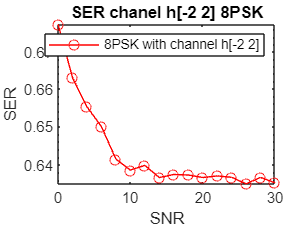

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%GIA  KANALI h[-2 2]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
pompos_kanali=conv(b,H2);
[SER6, BER6]=M_PSK(p_teliko,pompos_kanali,b,n,input,M);

semilogy(SNR,SER6,'ro-')
title('SER chanel h[-2 2] 8PSK' )
xlabel('SNR');
ylabel('SER');
legend('8PSK with channel h[-2 2]');

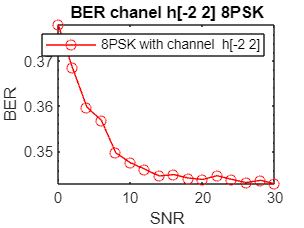


semilogy(SNR,BER6,'ro-')
title('BER chanel h[-2 2] 8PSK' )
xlabel('SNR');
ylabel('BER');
legend('8PSK with channel  h[-2 2]');

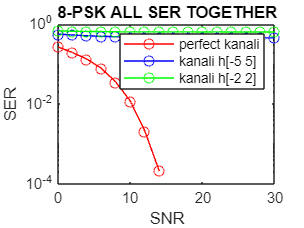

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ektiposi ola mazi SER gia 8-PSK
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
semilogy(SNR,SER4,'ro-')
hold on
semilogy(SNR,SER5,'bo-')
hold on
semilogy(SNR,SER6,'go-')
title('8-PSK ALL SER TOGETHER')
xlabel('SNR');
ylabel('SER');
legend('perfect kanali','kanali h[-5 5]','kanali h[-2 2]')
hold off

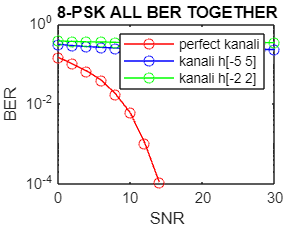

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ektiposi ola mazi BER gia 8_PSK
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
semilogy(SNR,BER4,'ro-')
hold on
semilogy(SNR,BER5,'bo-')
hold on
semilogy(SNR,BER6,'go-')
title('8-PSK ALL BER TOGETHER')
xlabel('SNR');
ylabel('BER');
legend('perfect kanali','kanali h[-5 5]','kanali h[-2 2]')
hold off

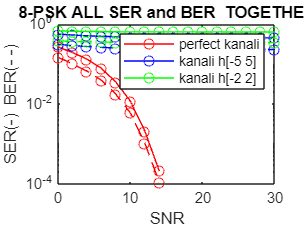



%BER KAI SER MAZI
semilogy(SNR,SER4,'ro-')
hold on
semilogy(SNR,SER5,'bo-')
hold on
semilogy(SNR,SER6,'go-')
hold on
semilogy(SNR,BER4,'ro--')
hold on
semilogy(SNR,BER5,'bo--')
hold on
semilogy(SNR,BER6,'go--')
hold off
title('8-PSK ALL SER and BER  TOGETHER')
xlabel('SNR');
ylabel('SER(-)  BER(- -)');
legend('perfect kanali','kanali h[-5 5]','kanali h[-2 2]')
hold off

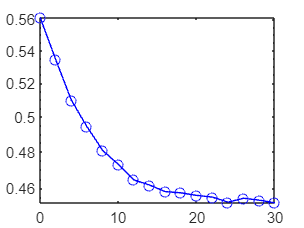


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TELOS 8-PSK
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%





semilogy(SNR,SER5,'bo-')